# $\ell_1$ norm optimized solution of the system of equations $A\mathbf{x}=\mathbf{b}$ is sparse.

# Compare least $\ell_1$ and $\ell_2$ norm solution of $A\mathbf{x}=\mathbf{b}$

clearvars

Construct $A$ and $\mathbf{b}$

n = 10;
m = 3;
A = randi([-5,5],m,n);
b = A*randi([-3,3],n,1)

b =     19
   -39
   -11


Find the least $\ell_2$ norm solution (using pseudo inverse)

x_2 = pinv(A)*b;

Find the least $\ell_1$ norm solution (using ADMM)

maxIter = 400;
rho = 1.6;

B1 = A'*pinv(A*A');
B1b = B1*b;
B2 = B1*A;
converged = false;
dz = 1e-6;

Initialize the $\mathbf{z}$ and $\mathbf{u}$ vectors

Z0 = rand(n,1);
U0 = rand(n,1);

for i = 1:maxIter
    % X update - using Shrinkage
    c = Z0 - U0;
    X1 = c - sign(c)/rho;
    X1(sign(X1) ~= sign(c)) = 0;
    % Z update - using Projection
    mu = X1 + U0;
    Z1 = (eye(n) - B2)*mu + B1b;
    % U update - using gradient
    U1 = U0 + (X1 - Z1);
    if(norm(Z1-Z0) <= dz)
        converged = true;
        break
    end
    fprintf("iter : %d \t dz : %f dxz : %f \n",i,norm(Z1-Z0),norm(X1-Z0));
    % fprintf("iter : %d \t dz : %f\n",i,norm(X1-Z0));
    Z0 = Z1; 
    U0 = U1;
end

iter : 1 	 dz : 3.258914 dxz : 1.766320 
iter : 2 	 dz : 0.836954 dxz : 1.782286 
iter : 3 	 dz : 0.479248 dxz : 0.561535 
iter : 4 	 dz : 0.414353 dxz : 0.432155 
iter : 5 	 dz : 0.390348 dxz : 0.397540 
iter : 6 	 dz : 0.341284 dxz : 0.342971 
iter : 7 	 dz : 0.183572 dxz : 0.229237 
iter : 8 	 dz : 0.129540 dxz : 0.184025 
iter : 9 	 dz : 0.142058 dxz : 0.159554 
iter : 10 	 dz : 0.142394 dxz : 0.146112 
iter : 11 	 dz : 0.135763 dxz : 0.138736 
iter : 12 	 dz : 0.131979 dxz : 0.134605 
iter : 13 	 dz : 0.129524 dxz : 0.132208 
iter : 14 	 dz : 0.128253 dxz : 0.130756 
iter : 15 	 dz : 0.128520 dxz : 0.129840 
iter : 16 	 dz : 0.129006 dxz : 0.129242 
iter : 17 	 dz : 0.128812 dxz : 0.128841 
iter : 18 	 dz : 0.128274 dxz : 0.128567 
iter : 19 	 dz : 0.127959 dxz : 0.128378 
iter : 20 	 dz : 0.127965 dxz : 0.128246 
iter : 21 	 dz : 0.124088 dxz : 0.124234 
iter : 22 	 dz : 0.094803 dxz : 0.099062 
iter : 23 	 dz : 0.092867 dxz : 0.095436 
iter : 24 	 dz : 0.092873 dxz : 0.094293 
i

x_1 = X1;

if(converged == true)
    fprintf("L1 norm optimized solution found after %d iterations. \n",i);
elseif(converged == false)
    fprintf("Convergence failed\n")
    fprintf("Try : increasing the no: iteration, increasing the convergence tol value, changing rho\n");
end

L1 norm optimized solution found after 113 iterations. 


Plot to check the solution vector $X$ and surrogate variable $Z$

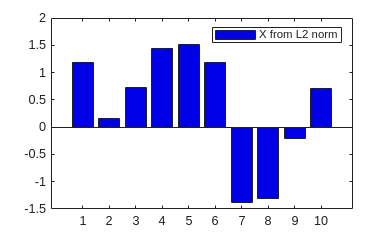

b2 = bar(x_2);%;hold on;
b2.FaceColor = [0 0 0.9];
legend("X from L2 norm")

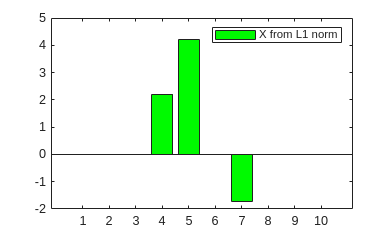


b1 = bar(x_1);%hold off
b1.FaceColor = [0 0.98 0];
legend("X from L1 norm")

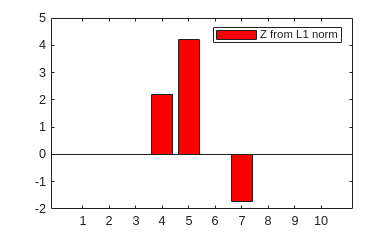


b1 = bar(Z1);%hold off
b1.FaceColor = [0.98 0 0];
legend("Z from L1 norm")

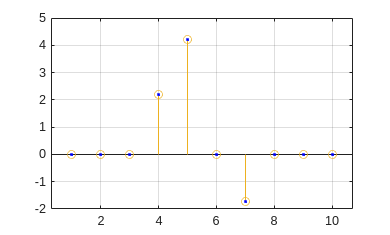


plot(X1,'k.');hold on
stem(X1)
stem(Z1)
plot(Z1,'b.');hold off
grid on

Check the error vector $A\mathbf{x}-\mathbf{b}$

e1 = A*x_1-b

e1 = 1.0e-04 *

   -0.2632
    0.0214
   -0.0122


e2 = A*x_2-b

e2 = 1.0e-13 *

   -0.1066
    0.2842
         0


Check the sparsity of the solution

sum(x_1 ~= 0)

ans = 3

sum(x_2 ~= 0)

ans = 10

cd("/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/")
mlxfile = matlab.desktop.editor.getActive().Filename;
outfile = mlxfile + ".pdf";
export(matlab.desktop.editor.getActive().Filename, outfile,PageSize="A4");